# Matlab基础

和学习其他所有语言一样，本文从matlab的基本数据结构，流程控制和函数等几个方面展开。本文完全参考matlab[官方文档](https://ww2.mathworks.cn/help/releases/R2019a/index.html)。

## 基础数据结构

matlab是脚本代码，因此可以直接在命令行窗口执行代码，这里就不再赘述了。因为matlab是基于矩阵的语言。所以从矩阵和数组开始本文。

**所有 MATLAB 变量都是多维*****数组***，与数据类型无关。MATLAB 不需要任何类型声明或维度说明。当 MATLAB 遇到新的变量名称时，它会自动创建变量，并分配适当大小的存储。如果此变量已存在，MATLAB 会更改其内容，并根据需要分配新存储。

*矩阵*是指通常用来进行线性代数运算的二维数组。

MATLAB 使用传统的十进制记数法以及可选的小数点和前导加号或减号来表示数字。科学记数法使用字母 e 来指定 10 次方的缩放因子。虚数使用 i 或 j 作为后缀。

### 数组和矩阵

#### 初始化

可以直接赋值，因为python的矩阵运算可能是借鉴了matlab，因此matlab的初始化和python的很相似，也包括zeros，ones，rand等。

a = [1 2 3 4];
m = [1 2 3; 4 5 6; 7 8 10];
z = zeros(5,1);
% 横向串联
A=[a,a];
% 纵向串联
B=[a;a];
% 使用冒号运算符及较通用的格式 start:step:end 创建等距向量值
C=0:10:100;
% rand 均匀分布的随机元素；randn 正态分布的随机元素
N = fix(10*rand(1,10));
R = randn(4,4);
% 删除 列可使用
A(:,2) = []

A =      1     3     4     1     2     3     4


% 单位矩阵
I=eye(3,3)

I =      1     0     0
     0     1     0
     0     0     1


#### 运算

matlab的运算是很强大的。运算主要包括5类：算术、逻辑、集合、位。相对需要花时间记忆下的主要是后两种运算，其他的和别的语言差不多，集合运算和python的numpy中的运算类似。位运算只是符号表示不同。另外注意matlab中变量都是数组，所以运算是围绕矩阵运算开展的。

% element-wise 运算
m2=m + 10;
b=a.*3;
% 矩阵转置
mt=m';
% 矩阵乘法
p = m*m;
q=m/m;
% 按位运算
A = uint8([0 1; 0 1]);
B = uint8([0 0; 1 1]);
TTable = bitand(A, B);

#### 索引

M = magic(4);
a1=M(4,2);
% 赋值新元素
M(4,5) = 17;
% 引用多个数组元素可以使用冒号运算符
a2=M(1:3,2);
a3=M(3,:);
% find 函数可用于确定与指定逻辑条件相符的数组元素的索引
A=magic(4);
k = find(isprime(A))';

### 文本和字符

将字符序列括在单引号中。可以将文本赋给变量。如果文本包含单引号，请在定义中使用两个单引号。

myText = 'Hello, world';
otherText = 'You''re right';
whos myText;

  Name        Size            Bytes  Class    Attributes

  myText      1x12               24  char               



与所有 MATLAB变量一样，myText 和 otherText 为数组。其*类*或数据类型为 char（*character* 的缩略形式）。可以使用方括号串联字符数组，就像串联数值数组一样。

longText = [myText,' - ',otherText];

要将数值转换为字符，请使用 num2str 或 int2str 等函数。

f = 71;
c = (f-32)/1.8;
tempText = ['Temperature is ',num2str(c),'C'];

### **日期和时间**

t = datetime('now','TimeZone','local','Format','d-MMM-y HH:mm:ss Z');
% 基于字符串向量创建日期，matlab是基于矩阵运算的，所以这类操作中也是很明显的矩阵形式运算
DateStrings = {'2014-05-26';'2014-08-03'};
t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');

### **分类数组**

categorical 是用于存储具有以下特征的数据的数据类型：此类数据值来自**离散分类有限集合**。这些分类可以采用自然排序，但并不要求一定如此。分类数组可用来有效地存储并方便地*处理非数值数据*，同时还为数值赋予有意义的名称。

% 向量元胞数组
state = {'MA','ME','CT','VT','ME','NH','VT','MA','NH','CT','RI'};
% 将元胞数组 state 转换为未采用数学排序的分类数组
state = categorical(state);
class(state);
categories(state);

### **表**

使用 table 数据类型来将**混合类型的数据和元数据属性（例如变量名称、行名称、说明和变量单位）收集到单个容器中**。表适用于列向数据或表格数据，这些数据通常以列形式存储于文本文件或电子表格中。例如，可以使用表存储试验数据，使用行表示不同的观测对象，使用列表示不同的测量变量。

load patients
BloodPressure = [Systolic Diastolic];
Gender = categorical(Gender);

whos('Gender','Age','Smoker','BloodPressure');

  Name                 Size            Bytes  Class          Attributes

  Age                100x1               800  double                   
  BloodPressure      100x2              1600  double                   
  Gender             100x1               346  categorical              
  Smoker             100x1               100  logical                  



T = table(Gender,Age,Smoker,BloodPressure);
T(1:5,:);

[T](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/readtable.html#btx_238-1_sep_shared-T) = readtable([filename](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/readtable.html#btx_238-1-filename)) 通过从文件中读取列向数据来创建表。

readtable 基于文件的扩展名确定文件格式：

- .txt、.dat 或 .csv（适用于带分隔符的文本文件）

- .xls、.xlsb、.xlsm、.xlsx、.xltm、.xltx 或 .ods（适用于电子表格文件）

### **时间表**

timetable 是一种特定类型的表，其中每一行关联一个时间。与 table 一样，timetable 数据类型可以存储具有不同数据类型和不同大小的列向数据变量，只要它们具有相同的行数即可。此外，时间表提供了特定于时间的函数，可对一个或多个时间表进行对齐、合并，以及执行计算。

indoors = readtable('indoors.csv');
indoors = table2timetable(indoors);

### **元胞数组**

元胞数组是一种包含名为元胞的**索引数据容器**的数据类型，其中的每个元胞都可以包含任意类型的数据。元胞数组通常包含文本字符串列表、文本和数字的组合或不同大小的数值数组。通过将索引括在圆括号 () 中可以引用元胞集。使用花括号 {} 进行索引来访问元胞的内容。

myCell = {1, 2, 3;
          'text', rand(5,10,2), {11; 22; 33}};
emptyCell = cell(3,4,2);

C = {'one', 'two', 'three'; 
     1, 2, 3}

C = 2×3 cell 数组
    {'one'}    {'two'}    {'three'}
    {[  1]}    {[  2]}    {[    3]}


% 使用圆括号 () 的元胞索引
upperLeft = C(1:2,1:2)

upperLeft = 2×2 cell 数组
    {'one'}    {'two'}
    {[  1]}    {[  2]}


C(1,1:3) = {'first','second','third'};
% 使用花括号 {} 的内容索引
last = C{2,3};
C{2,3} = 300;

### **结构体**

结构体是多维 MATLAB 数组，包含可按文本*字段标志符*访问的元素。

S.name = 'Ed Plum';
S.score = 83;
S.grade = 'B+'

S = 包含以下字段的 struct :
     name: 'Ed Plum'
    score: 83
    grade: 'B+'


### 函数句柄

可以创建任何 MATLAB函数的句柄，并将该句柄用作引用该函数的一种方式。函数句柄通常在参数列表中传递给其他函数，然后，**其他函数可以使用该句柄执行或*****计算*****相应函数**。（个人理解，就是函数可以赋给新的变量引用，这个引用就是句柄）

### 映射容器

*映射*是一种快速的键查找数据结构体，可用于灵活地对其单个元素进行索引。与 MATLAB软件中仅允许通过整数索引获取元素的大多数数组数据结构体不同，映射的**索引几乎可以是任何数值标量或字符向量**。

指向映射元素的索引称为*键*。这些键以及与其相关的数据*值*都存储在映射内。映射的每个条目都包含一个唯一键及其相应的值。

keySet = {'Jan','Feb','Mar','Apr'};
valueSet = [327.2 368.2 197.6 178.4];
M = containers.Map(keySet,valueSet);

### 时序对象

MATLAB时序对象有两种类型：

- [timeseries](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/timeseries.html) - 存储数据和时间值，以及包含单位、事件、数据质量和插值方法的元数据信息

- [tscollection](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/tscollection.html) - 存储共享公共时间向量的 timeseries 对象的集合，便于对具有不同单位的同步时序执行操作

timeseries 对象在其属性中包含描述动态过程的数据和时间信息。可以使用 timeseries 对象函数来创建、修改和分析时序的行为。

load count.dat
count;
count1 = timeseries(count(:,1), 1:24,'name', 'intersection1');
count2 = timeseries(count(:,2), 1:24,'name', 'intersection2');
count3 = timeseries(count(:,3), 1:24,'name', 'intersection3');

Iteration #1


sampleMean =     0.4898    0.5055    0.4684    0.4984    0.4530


Iteration #2


sampleMean =     0.4898    0.4695    0.4684    0.4984    0.4530


Iteration #3


sampleMean =     0.4898    0.4695    0.5452    0.4984    0.4530


Iteration #4


sampleMean =     0.4898    0.4695    0.5452    0.4923    0.4530


Iteration #5


sampleMean =     0.4898    0.4695    0.5452    0.4923    0.5522


### 全局变量

想要多个函数共享一个变量副本，只需在所有函数中将此变量声明为 [global](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/global.html)。

## **循环及条件语句**

在脚本中，可以使用关键字 for、while、if 和 switch 循环并有条件地执行代码段。

nsamples = 5;

overallMean = 0.5098

npoints = 50;
% for循环用end结束，取值范围用冒号界定
for k = 1:nsamples
   iterationString = ['Iteration #',int2str(k)];
   % 输出用disp
   disp(iterationString)
   currentData = rand(npoints,1);
   sampleMean(k) = mean(currentData)

Mean is within the expected range


end
overallMean = mean(sampleMean)
% if语句也以end收尾，写法是if-elseif-else


function r = rank(A,tol)
%RANK   Matrix rank.
%   RANK(A) provides an estimate of the number of linearly
%   independent rows or columns of a matrix A.
%
%   RANK(A,TOL) is the number of singular values of A
%   that are larger than TOL. By default, TOL = max(size(A)) * eps(norm(A)).
%
%   Class support for input A:
%      float: double, single

%   Copyright 1984-2015 The MathWorks, Inc.

s = svd(A);
if nargin==1
   tol = max(size(A)) * eps(max(s));
end
r = sum(s > tol);


if overallMean < .49
   disp('Mean is less than expected')
elseif overallMean > .51
   disp('Mean is greater than expected')
else
   disp('Mean is within the expected range')
end

## 函数与基本库

matlab中函数定义是如下形式：

type rank

函数的第一行以关键字 [function](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/function.html) 开头。它提供函数名称和参数顺序。本示例中具有两个输入参数和一个输出参数。注意输入输出形参都在一开始定义好了。

因为matlab是针对矩阵的运算，因此最基本的运算就是矩阵的基本运算了。

### 函数类型

#### **匿名函数**

*匿名函数*是一种简单形式的 MATLAB 函数，该函数在一个 MATLAB 语句中定义。它包含一个 MATLAB 表达式和任意数目的输入和输出参数。

sqr = @(x) x.^2;
a = sqr(5);

#### **嵌套函数**

可以在函数体中定义其他函数。这些函数称为外部函数中的*嵌套*函数。嵌套函数包含任何其他函数的任何或所有组成部分。主函数赋值的变量可以由嵌套在主函数中的任意级别的函数读取或覆盖。类似地，嵌套函数中赋值的变量可以由包含该函数的任何函数读取或被覆盖。

### **矩阵求和、转置和对角矩阵**

举例幻方矩阵magic，沿任何行或列求和，或者沿两条主对角线中的任意一条求和，都将始终得到相同数字。

A = [16 3 2 13; 5 10 11 8; 9 6 7 12; 4 15 14 1];
sumA=sum(A);
sumAt=sum(A')';
% 在 sum 函数中使用维度参数（维度从1开始计数的）：
sumAt=sum(A,2);
% 使用 sum 和 diag 函数可以获取主对角线上的元素的总和：
sumDiagA=sum(diag(A));
% 函数 fliplr 可以从左往右地翻转矩阵：
filpSum=sum(diag(fliplr(A)));

### 基本绘图函数

plot 函数具有不同的形式，具体取决于输入参数。

- 如果 y 是向量，plot(y) 会生成 y 元素与 y 元素索引的分段线图。

- 如果有两个向量被指定为参数，plot(x,y) 会生成 y 对 x 的图形。

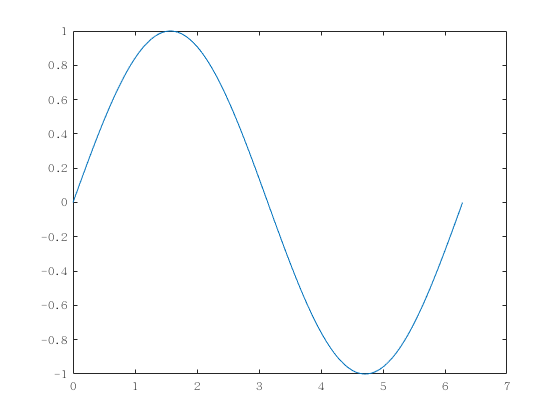

x = 0:pi/100:2*pi;
y = sin(x);

plot(x,y);

通过调用一次 plot，多个 x-y 对组参数会创建多幅图形。MATLAB对每条线使用不同的颜色。

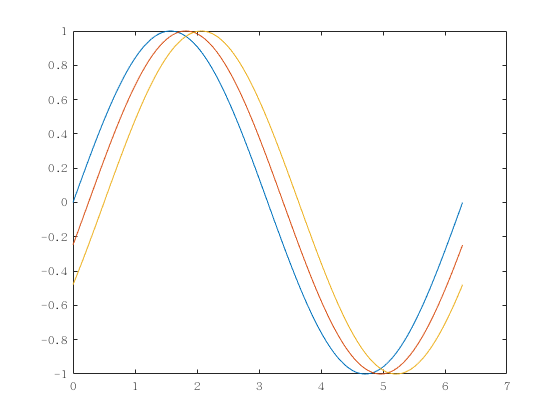

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)

### 显示图像

可以将二维数值数组显示为*图像*。在图像中，数组元素决定了图像的亮度或颜色。例如，加载一个图像数组及其颜色图：

load durer
whos

  Name                            Size               Bytes  Class              Attributes

  A                               4x4                  128  double                       
  Age                           100x1                  800  double                       
  B                               2x4                   64  double                       
  BloodPressure                 100x2                 1600  double                       
  C                               2x3                  728  cell                         
  DateStrings                     2x1                  264  cell                         
  Diastolic                     100x1                  800  double                       
  Gender                        100x1                  346  categorical                  
  Height                        100x1                  800  double                       
  I                               3x3                   72  double                       
  LastNam

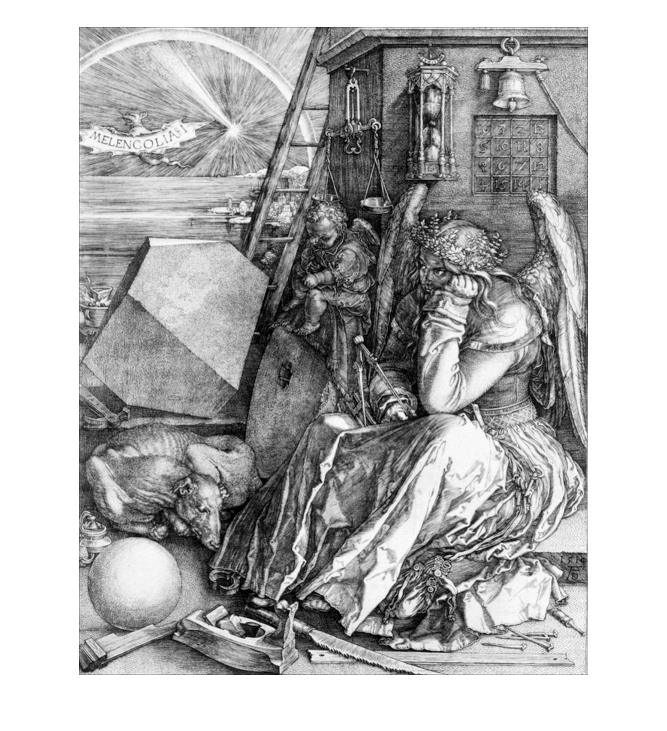

imshow(X,map)

使用 [imread](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/imread.html) 函数可以读取标准图像文件（TIFF、JPEG、PNG 等）。imread 返回的数据类型取决于读取的图像类型。

使用 [imwrite](https://ww2.mathworks.cn/help/releases/R2019a/matlab/ref/imwrite.html) 函数可以将 MATLAB 数据写入到各种标准图像格式。